Compute the Numeric Differential for scalar or vector function,  and the numeric gradient for matrix function

Problem description :

Function $f\left(x\right)=4−\text{ }{\left(x−2\right)}^2$ within the range [0, 3], we need to compute its 2-points forwarding differential value and inner-point central diffential (i.e. gradient)

and plot their graphs.

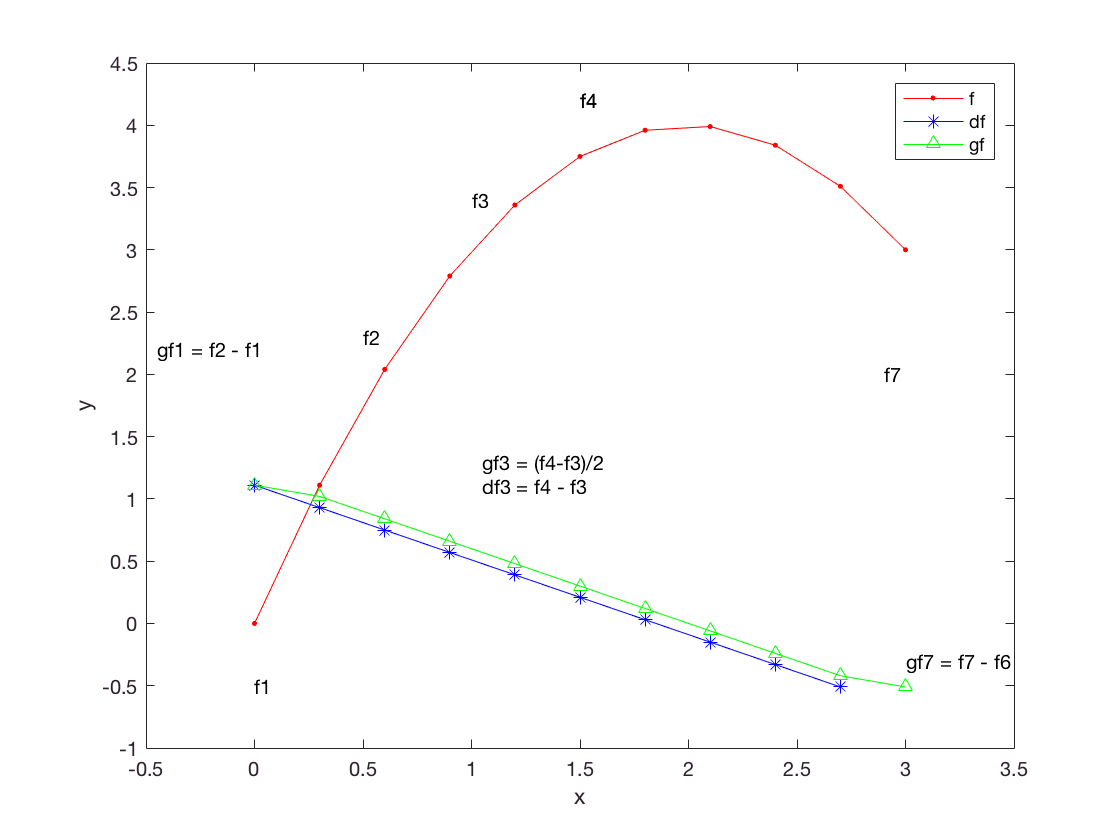

clear;
clf;

sampling_step_size = 0.4;        % the sampling step for independent argument
sampling_points_x = 0:sampling_step_size:3;    % total sampling points for independent argument : x
func_points = 4 - (sampling_points_x - 2).^2;    % function points

% Plot the native function graph
plot(sampling_points_x, func_points, 'r.-');
df = diff(func_points);    % The forward differential points set.
gf = gradient(func_points);    % The interal central differential points set 
hold on;

df_x = sampling_points_x(1:end-1);
% Plot the differential function
plot(df_x, df, 'b*-');
% Plot the gradient function 
plot(sampling_points_x, gf, 'g^-');
legend('f', 'df', 'gf');
text(1, 3.4, 'f3');
text(1.5, 4.2, 'f4');
text(1.05, 1.1, 'df3 = f4 - f3')

text(0, -0.5, 'f1')
text(2.9, 2,4, 'f7')
text(-0.45, 2.2, 'gf1 = f2 - f1')

text(3, -0.3, 'gf7 = f7 - f6')
text(0.5, 2.3, 'f2')
text(1.5, 4.2, 'f4')
text(1.05, 1.3, 'gf3 = (f4-f3)/2')

axis([-0.5, 3.5, -1, 4.5]);
xlabel('x');
ylabel('y');
box on
hold off;